# Expand Example 3.45:

This live script is for use with the textbook

*Continuous-Time Signals and Systems: A MATLAB Integrated Approach*

by Oktay Alkin, CRC Press, 2025.

The system function for the system under consideration is

        $H(f)=\frac{1}{1+j(f/80)}$                    (3.351)

and the input signal is

        
$$x(t)=5\,\cos(2\pi ft)$$


f = 200; % Input frequency

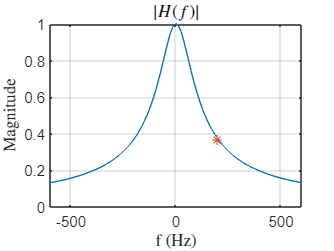

% Define an anonymous function for H(f)
H = @(f) 1./(1+j*f/80);
frq = [-600:600];  % Vector of frequencies
plot(frq,abs(H(frq)),f,abs(H(f)),'*'); grid;
set(0,'defaultTextInterpreter','latex');
xlabel('f (Hz)');
ylabel('Magnitude')
title('$|H(f)|$');

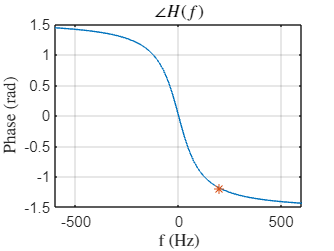

plot(frq,angle(H(frq)),f,angle(H(f)),'*'); grid;
set(0,'defaultTextInterpreter','latex');
xlabel('f (Hz)');
ylabel('Phase (rad)')
title('$\angle H(f)$');

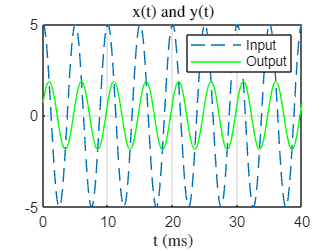


% Compute the magnitude and the phase of the system function
% at the frequency of interest
Hmag = abs(H(f));
Hphs = angle(H(f));
% Compute the steady-state response to a sinusoid with frequency f
t = [0:0.05:40];  % Time instants in milliseconds
x = 5*cos(2*pi*f*t/1000);
y = 5*Hmag*cos(2*pi*f*t/1000+Hphs);
% Graph input and output signals together
plot(t,x,'--',t,y,'g'); grid;
xlabel('t (ms)');
title('x(t) and y(t)');
legend('Input','Output');

set(0,'defaultTextInterpreter','tex');